syms p C1 C2 B0
%当p<=pt时u的最大值
u_bmax=(2*p*log(-(2*p - C1*C2 + C1*C2*sqrt(-(4*p - C1*C2)/(C1*C2)))/(2*p)) + C1*C2 - 2*B0*C2*p + C1*C2*sqrt(-(4*p - C1*C2)/(C1*C2)))/(2*C2);
u_bmax=subs(u_bmax,[C1,C2,B0],[30,0.05,20])

$$u\_bmax = 20\,p\,\log\left(-\frac{2\,p+\frac{3\,\sqrt{1-\frac{8\,p}{3}}}{2}-\frac{3}{2}}{2\,p}\right)-20\,p+15\,\sqrt{1-\frac{8\,p}{3}}+15$$

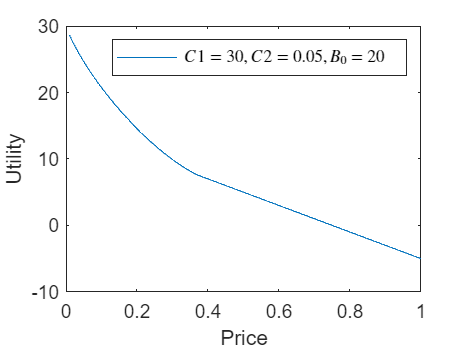

price = 0.01:0.001:0.375;
u_bmax=subs(u_bmax,p,price);
u_pmax = C1/2-p*B0;
u_pmax =subs(u_pmax,[C1,B0],[30,20]);
price2 = 0.376 : 0.001 :1;
u_pmax=subs(u_pmax,p,price2);
u=[u_bmax,u_pmax];
b=[price,price2];
plot(b,u);
legend("$C1=30,C2=0.05,B_{0}=20$",'Interpreter','latex')
xlabel("Price");
ylabel("Utility")